**Name: Destinie James**

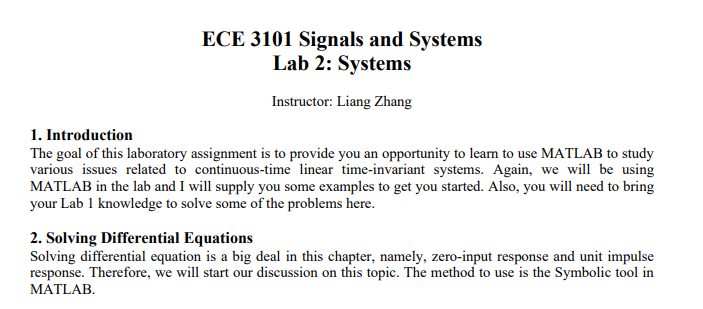

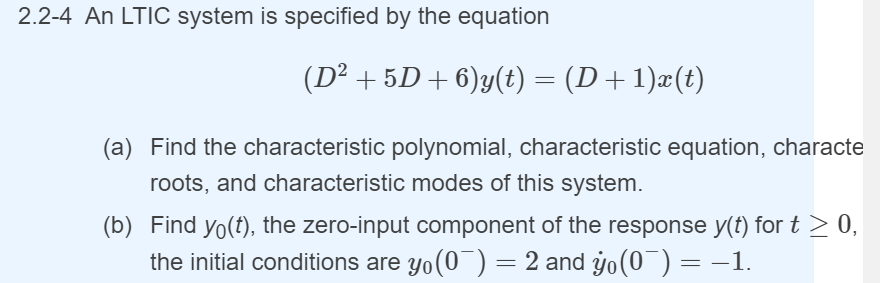

**Part (a): Characteristic Polynomial, Roots, and Modes**

syms D
% Define the characteristic polynomial
charPoly = D^2 + 5*D + 6;

% Find roots of the characteristic polynomial
charRoots = roots(sym2poly(charPoly));

% Display the characteristic polynomial and roots
fprintf('Characteristic Polynomial: %s\n', charPoly);

Characteristic Polynomial: 5*D + D^2 + 6


disp('Roots of the characteristic polynomial:');

Roots of the characteristic polynomial:


disp(charRoots);

   -3.0000
   -2.0000




% Calculate and display the characteristic modes
syms t
modes = exp(charRoots*t);
disp('Characteristic modes:');

Characteristic modes:


disp(modes);

$$\left(\begin{array}{c} {\mathrm{e}}^{-3\,t}\\ {\mathrm{e}}^{-2\,t} \end{array}\right)$$

**Part (b): Zero-Input Component of the Response**

syms y(t)
Dy = diff(y);
D2y = diff(y,2);
% Homogeneous differential equation corresponding to zero-input response
ode = D2y + 5*Dy + 6*y == 0;
% Initial conditions
cond1 = y(0) == 2;
cond2 = Dy(0) == -1;
% Solve the differential equation
ySol(t) = dsolve(ode, [cond1, cond2]);
% Display the solution
disp('Zero-input component of the response y0(t):');

Zero-input component of the response y0(t):


disp(ySol(t));

$$5\,{\mathrm{e}}^{-2\,t}-3\,{\mathrm{e}}^{-3\,t}$$

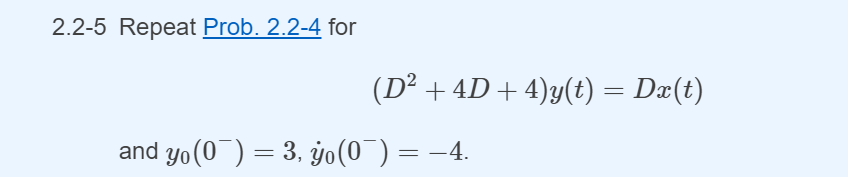

**Part (a): Characteristic Polynomial, Roots, and Modes**

% Part (a): Characteristic Polynomial, Roots, and Modes for 2.2-5
syms D y(t) t

% Define the differential equation (homogeneous part)
homogeneous_eqn_225 = (D^2 + 4*D + 4)*y(t) == 0;

% Extract the characteristic polynomial
char_poly_225 = simplify(lhs(homogeneous_eqn_225));

% Solve for the roots of the characteristic equation
char_roots_225 = solve(char_poly_225 == 0, D);

% Determine the characteristic modes based on the roots
char_modes_225 = exp(char_roots_225 * t);

% Display results
disp('Characteristic Polynomial for 2.2-5:');

Characteristic Polynomial for 2.2-5:


disp(char_poly_225);

$$y\left(t\right)\,{\left(\text{D}+2\right)}^{2}$$

disp('Characteristic Equation for 2.2-5:');

Characteristic Equation for 2.2-5:


disp(char_poly_225 == 0);

$$y\left(t\right)\,{\left(\text{D}+2\right)}^{2}=0$$

disp('Roots for 2.2-5:');

Roots for 2.2-5:


disp(char_roots_225);

$$\left(\begin{array}{c} -2\\ -2 \end{array}\right)$$

disp('Characteristic Modes for 2.2-5:');

Characteristic Modes for 2.2-5:


disp(char_modes_225);

$$\left(\begin{array}{c} {\mathrm{e}}^{-2\,t}\\ {\mathrm{e}}^{-2\,t} \end{array}\right)$$

**Part (b): Solve the Full Differential Equation (Inhomogeneous)**


syms y(t) Dy
D2y = diff(y, t, 2);  % Define the second derivative
Dy = diff(y, t);       % First derivative

% Define the homogeneous differential equation corresponding to zero-input response
hom_eqn_225 = D2y + 4*Dy + 4*y == 0;

% Initial conditions provided in the problem statement
cond1_225 = y(0) == 3;
cond2_225 = Dy(0) == -4;  % Correct derivative notation used here

% Solve the differential equation using defined derivatives
ySol_225(t) = dsolve(hom_eqn_225, cond1_225, cond2_225);

% Display the zero-input response
disp('Zero-input component of the response for 2.2-5:');

Zero-input component of the response for 2.2-5:


disp(vpa(ySol_225(t), 4));  % Using vpa for better numerical precision in display

$$3.0\,{\mathrm{e}}^{-2.0\,t}+2.0\,t\,{\mathrm{e}}^{-2.0\,t}$$

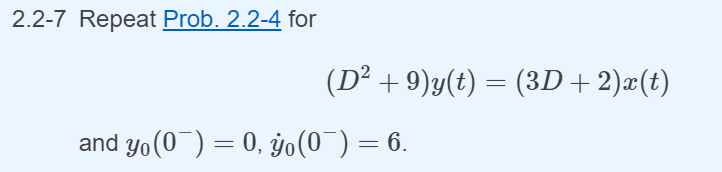

**Part (a): Characteristic Polynomial, Roots, and Modes**

% Part (a): Characteristic Polynomial, Roots, and Modes for 2.2-7
syms D y(t) t

% Define the differential equation (homogeneous part)
homogeneous_eqn_227 = (D^2 + 9)*y(t) == 0;

% Extract the characteristic polynomial
char_poly_227 = simplify(lhs(homogeneous_eqn_227));

% Solve for the roots of the characteristic equation
char_roots_227 = solve(char_poly_227 == 0, D);

% Determine the characteristic modes based on the roots
char_modes_227 = exp(char_roots_227 * t);

% Display results
disp('Characteristic Polynomial for 2.2-7:');

Characteristic Polynomial for 2.2-7:


disp(char_poly_227);

$$y\left(t\right)\,\left({\text{D}}^{2}+9\right)$$

disp('Characteristic Equation for 2.2-7:');

Characteristic Equation for 2.2-7:


disp(char_poly_227 == 0);

$$y\left(t\right)\,\left({\text{D}}^{2}+9\right)=0$$

disp('Roots for 2.2-7:');

Roots for 2.2-7:


disp(char_roots_227);

$$\left(\begin{array}{c} -3\,\mathrm{i}\\ 3\,\mathrm{i} \end{array}\right)$$

disp('Characteristic Modes for 2.2-7:');

Characteristic Modes for 2.2-7:


disp(char_modes_227);

$$\left(\begin{array}{c} {\mathrm{e}}^{-3\,t\,\mathrm{i}}\\ {\mathrm{e}}^{3\,t\,\mathrm{i}} \end{array}\right)$$

**Part (b): Zero-Input Response**

% Part (b): Zero-input response for 2.2-7
syms y(t) Dy
D2y = diff(y, t, 2);  % Define the second derivative
Dy = diff(y, t);       % First derivative

% Define the homogeneous differential equation corresponding to zero-input response
hom_eqn_227 = D2y + 9*y == 0;

% Initial conditions provided in the problem statement
cond1_227 = y(0) == 0;
cond2_227 = Dy(0) == 6;  % Correct derivative notation used here

% Solve the differential equation using defined derivatives
ySol_227(t) = dsolve(hom_eqn_227, [cond1_227, cond2_227]);

% Display the zero-input response
disp('Zero-input component of the response for 2.2-7:');

Zero-input component of the response for 2.2-7:


disp(vpa(ySol_227(t), 4));  % Using vpa for better numerical precision in display

$$2.0\,\sin\left(3.0\,t\right)$$

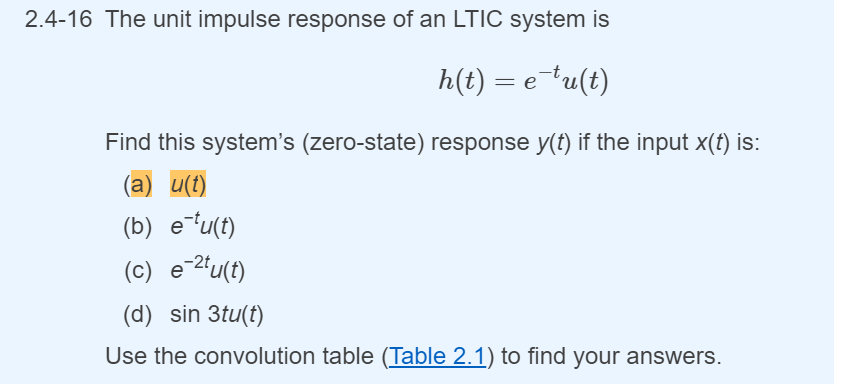

% Unit impulse response: h(t) = e^(-t)u(t)
syms t tau u(t) h(t) x(t) y(t)
h(t) = exp(-t) * heaviside(t);  % Impulse response

% Inputs for different parts:
% (a) u(t)
x(t) = heaviside(t);
y(t) = int(h(tau) * subs(x(t), t, t-tau), tau, -inf, inf);
disp(simplify(y(t)));

$$\frac{{\mathrm{e}}^{-t}\,\left({\mathrm{e}}^{t}-1\right)\,\left(\mathrm{sign}\left(t\right)+1\right)}{2}$$


% (b) e^(-t)u(t)
x(t) = exp(-t) * heaviside(t);
y(t) = int(h(tau) * subs(x(t), t, t-tau), tau, -inf, inf);
disp(simplify(y(t)));

$$\frac{t\,{\mathrm{e}}^{-t}\,\left(\mathrm{sign}\left(t\right)+1\right)}{2}$$


% (c) e^(-2t)u(t)
x(t) = exp(-2*t) * heaviside(t);
y(t) = int(h(tau) * subs(x(t), t, t-tau), tau, -inf, inf);
disp(simplify(y(t)));

$$\frac{{\mathrm{e}}^{-2\,t}\,\left({\mathrm{e}}^{t}-1\right)\,\left(\mathrm{sign}\left(t\right)+1\right)}{2}$$


% (d) sin(3t)u(t)
x(t) = sin(3*t) * heaviside(t);
y(t) = int(h(tau) * subs(x(t), t, t-tau), tau, -inf, inf);
disp(simplify(y(t)));

$$-\left(\frac{\mathrm{sign}\left(t\right)}{2}+\frac{1}{2}\right)\,\left(-\frac{3\,{\mathrm{e}}^{-t}}{10}+{\mathrm{e}}^{-3\,t\,\mathrm{i}}\,\left(\frac{3}{20}-\frac{1}{20}\,\mathrm{i}\right)+{\mathrm{e}}^{3\,t\,\mathrm{i}}\,\left(\frac{3}{20}+\frac{1}{20}\,\mathrm{i}\right)\right)$$

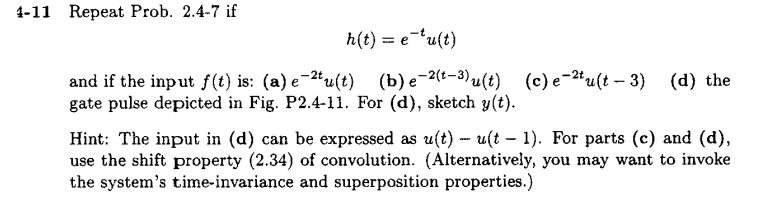

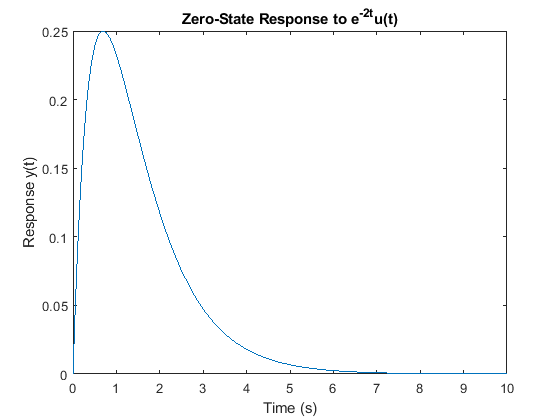

syms t tau u(t) h(t) f(t) y(t)
u(t) = heaviside(t);  % Heaviside step function
h(t) = exp(-t) * u(t);  % Unit impulse response

% (a) Input: f(t) = e^(-2t)u(t)
f(t) = exp(-2*t) * u(t);
y(t) = int(h(tau) * subs(f(t), t, t-tau), tau, -inf, inf);
figure;
fplot(y(t), [0, 10]);
title('Zero-State Response to e^{-2t}u(t)');
xlabel('Time (s)');
ylabel('Response y(t)');

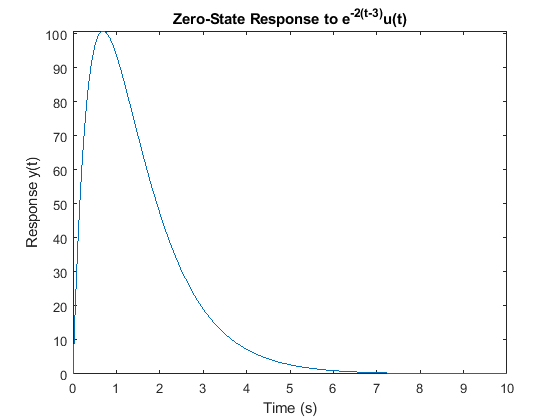


% (b) Input: f(t) = e^(-2*(t-3))u(t)
f(t) = exp(-2*(t-3)) * u(t);
y(t) = int(h(tau) * subs(f(t), t, t-tau), tau, -inf, inf);
figure;
fplot(y(t), [0, 10]);
title('Zero-State Response to e^{-2(t-3)}u(t)');
xlabel('Time (s)');
ylabel('Response y(t)');

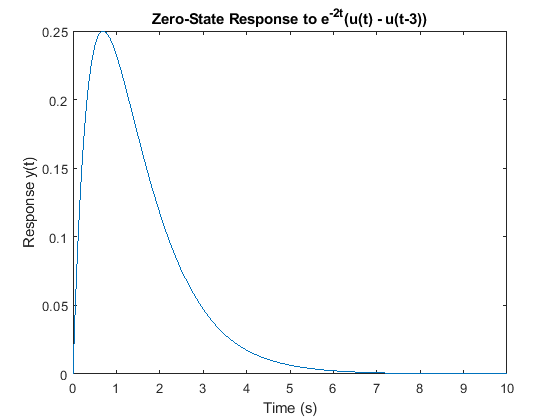


% (c) Input: f(t) = e^(-2t)(u(t) - u(t-3))
f(t) = exp(-2*t) * (u(t) - u(t-3));
y(t) = int(h(tau) * subs(f(t), t, t-tau), tau, -inf, inf);
figure;
fplot(y(t), [0, 10]);
title('Zero-State Response to e^{-2t}(u(t) - u(t-3))');
xlabel('Time (s)');
ylabel('Response y(t)');

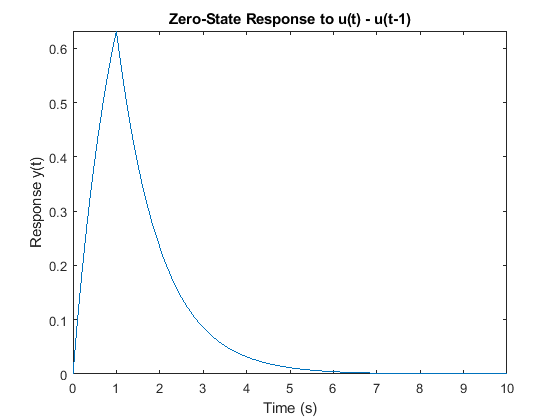


% (d) Input: f(t) = u(t) - u(t-1)
f(t) = u(t) - u(t-1);
y(t) = int(h(tau) * subs(f(t), t, t-tau), tau, -inf, inf);
figure;
fplot(y(t), [0, 10]);
title('Zero-State Response to u(t) - u(t-1)');
xlabel('Time (s)');
ylabel('Response y(t)');